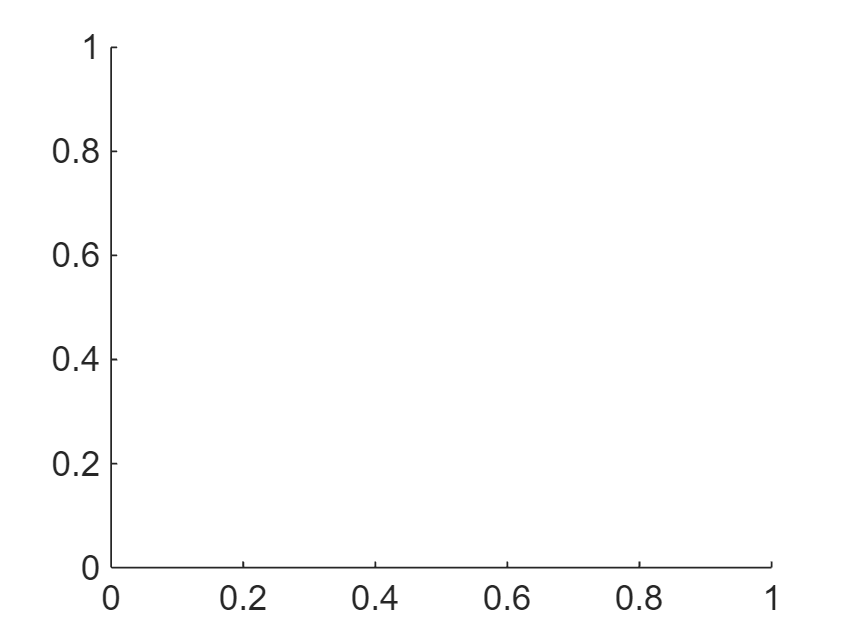


% ===== AUTHORS ===== %
% - Liam Murray
% - Sofia Simas
% - Lilly Mertzluft
% - Summer Chirpich
% - Satvik Kumar



% ===== INIT ========= %

[targetTime, targetPosX, targetPosY] = generateTargetPath();
astrobee = generateAstrobeeStruct();
dt = targetTime(2)-targetTime(1);



% ===== SIMULATE ===== %

thrustProfiles = solveThrustProfiles(targetTime, targetPosX, targetPosY, astrobee);

[time, posX, posY, velX, velY, theta, omega] = solvePath(astrobee, thrustProfiles, dt);



% ===== DISPLAY ===== %

% May be optional if drawnow is used in solvePath
renderAnimation(time, posX, posY, theta, thrustProfiles, astrobee);

% We will also need to render the thrust too, we should create a function for this
% Consider using drawnow
% Liam

